clear

% reading in the sea salt aerosol data
ssa_df = readtable("matt_derived_cvs.csv");
ssa_df = ssa_df(:,2:end);
ssa_df.("wind_rounded") = round(ssa_df.total_wind);

ssa_df 

ssa_df = 4927×11 table
    total_wind    um3_conc    um4_conc    um5_conc    um6_conc    um7_conc    um8_conc    um9_conc    um10_conc    run    wind_rounded
    __________    ________    ________    ________    ________    ________    ________    ________    _________    ___    ____________

      4.7636       58.204      24.272      10.492      4.7461      2.2777      1.1845     0.69152      0.48393      0          5      
      5.0593       58.204      24.272      10.492      4.7461      2.2777      1.1845     0.69152      0.48393      0          5      
      4.8256       58.204      24.272      10.492      4.7461 


% the number of dry radius bins (from 3um to 10um)
drad_nbins = 8;

% the number of wind bins (from 2m/s to 13m/s)
wind_nbins = 12;

num_samples = max(ssa_df.run)+1;
sample_num_vec = unique(ssa_df.run);

all_um_concs = cell(num_samples,drad_nbins);
um_winds = cell(num_samples,1);

for i = 1:length(sample_num_vec)
    tmp_sample_num = sample_num_vec(i);
    sample_idxs = find(ssa_df.run == tmp_sample_num);

    um_winds{i} = table2array(ssa_df(sample_idxs,"wind_rounded"));

    for j = 1:drad_nbins
        all_um_concs{i,j} = table2array(ssa_df(sample_idxs,1+j));
    end
end

correlation_time_vec = [18 16 14 12 10 8 6 5];

um_concs = cell(num_samples,drad_nbins);
for i = 1:size(um_winds,1)
    for j = 1:drad_nbins
        tmp_concs = all_um_concs{i,j};
        tmp_concs_length = length(tmp_concs);
        tmp_correlation_length = correlation_time_vec(j);
        tmp_min_hrs = min([tmp_correlation_length tmp_concs_length]);

        um_concs{i,j} = tmp_concs(1:tmp_min_hrs);
    end
end

full_ws_conc_ds = cell(1,drad_nbins);
for i = 1:num_samples
    tmp_winds = um_winds{i};
    tmp_all_concs = um_concs(i,:);
    for j = 1:drad_nbins
        tmp_concs = tmp_all_concs{j};
        tmp_winds_corr = tmp_winds(1:min([correlation_time_vec(j) length(tmp_winds)]));
        full_ws_conc_ds{j} = cat(1,full_ws_conc_ds{j},[tmp_winds_corr tmp_concs]);
    end
end

% The rows of wsX_concs represent the wind speed bins from 2m/s to 13m/s
% and the cols represent the dry radius size from 3um to 10um
wsX_concs = cell(wind_nbins,drad_nbins);
for i = 1:drad_nbins
    tmp_ws_conc_ds = full_ws_conc_ds{i};
    for ws = 2:wind_nbins+1
        tmp_idxs = find(tmp_ws_conc_ds(:,1)==ws);
        wsX_concs{ws-1,i} = tmp_ws_conc_ds(tmp_idxs,2);
    end
end

% Calculating the CDFs
wsX_conc_cds = cell(size(wsX_concs));
wsX_conc_xis = cell(size(wsX_concs));

for i = 1:size(wsX_conc_xis,2)
    for j = 1:size(wsX_conc_xis,1)
        if ~isempty(wsX_concs{j,i})
            % Using the kernel density for a non-parametric estimation of the cdf
            [wsX_conc_cds{j,i}, wsX_conc_xis{j,i}] = ksdensity(wsX_concs{j,i},"Function","cdf","Support","nonnegative","BoundaryCorrection","reflection","Kernel","normal");
        else
        end
    end
end

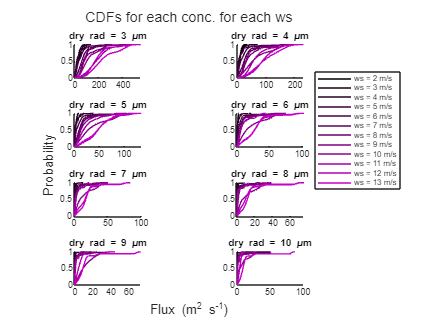

% Plotting the CDFs for each dry radius for each wind speed
figure;
pinks = [linspace(0,1,15)' linspace(0,0,15)' linspace(0,1,15)'];
tcount = tiledlayout(4,2);
for i = 1:size(wsX_conc_xis,2)
    nexttile;
    hold on
    for j = 1:size(wsX_conc_xis,1)
        plot(wsX_conc_xis{j,i},wsX_conc_cds{j,i},'Color',pinks(j,:))
    end
    hold off
    if i == 4 
        legend(["ws = 2 m/s","ws = 3 m/s","ws = 4 m/s","ws = 5 m/s","ws = 6 m/s","ws = 7 m/s","ws = 8 m/s","ws = 9 m/s","ws = 10 m/s","ws = 11 m/s","ws = 12 m/s","ws = 13 m/s"],'Location','eastoutside')
    end
    pbaspect([2 1 1])
    title("dry rad = " + string(i+2) + " \mum")
end

title(tcount, "CDFs for each conc. for each ws")
xlabel(tcount, "Flux (m^2 s^{-1})")
ylabel(tcount, "Probability")

% From flux to concentration
rng(22)

correlation_time_vec = [18 16 14 12 10 8 6 5];
marine_boundary_height = 500;
seconds_in_hour = 60*60;
correlation_r_vec = [0.9 0.8 0.7 0.6 0.5 0.4 0.3 0.2];

wind_gamma_dist = fitdist(ssa_df.total_wind,"Gamma");
wind_vec = gamrnd(wind_gamma_dist.a,wind_gamma_dist.b,23,1);

wind_rw = round(wind_vec) - 1;
wind_rw(wind_rw<1) = 1;
wind_rw(wind_rw>12) = 12;

single_column_flux = zeros(length(wind_rw),drad_nbins);
single_column_concentration = zeros(1,drad_nbins);
for ws_id = 1:length(wind_rw)
    ws = wind_rw(ws_id);
    u = rand(1);
    tmp_one_col_flux = zeros(1,drad_nbins);
    for j = 1:drad_nbins
        [tmp_prob, unique_idx] = unique(wsX_conc_cds{ws,j});
        tmp_flux = wsX_conc_xis{ws,j};
        tmp_flux = tmp_flux(unique_idx);
        tmp_one_col_flux(j) = interp1(tmp_prob, tmp_flux, u, 'linear', 'extrap');
    end
    single_column_flux(ws_id,:) = tmp_one_col_flux;
    for j = 1:drad_nbins
        single_column_concentration(j) = sum(single_column_flux(1:correlation_time_vec(j),j),1);
        single_column_concentration(j) = single_column_concentration(j).*correlation_r_vec(j).*marine_boundary_height;
    end
end
single_column_flux

single_column_flux =   107.5041   44.7442   19.8435    9.8107    5.4039    3.5106    2.3742    1.8295
   98.8567   45.8369   17.6538    6.4336    2.7756    2.0199    0.9702    0.8612
    9.1344    2.4966    0.8057    0.3615    0.1733    0.1015    0.0784    0.0967
   70.6911   27.3648   11.3120    4.7640    2.1536    1.0970    0.6671    0.4485
  107.8375   35.6161    8.0186    1.8649    0.5349    0.1445    0.0589    0.0817
  107.8906   44.6795   19.6742    9.0339    4.7501    2.8418    1.8943    1.4284
  119.4858   65.5625   35.9821   20.4901   13.1550   10.3032   11.9812    6.7961
   29.0784    9.7033    3.4710    1.5718    0.7368    0.3488    0.2693    0.3321
  447.1829  176.1489   79.4679   37.3907   19.7459   12.0181    7.4842    5.8352
   37.7064   11.7733    4.5120    1.9829    0.8309    0.3435    0.1854    0.4006


single_column_concentration

single_column_concentration = 1.0e+05 *

    8.6632    2.8804    0.8078    0.3027    0.1256    0.0407    0.0091    0.0033


% Needs some adjusting but it's okay
























% For the simulated data, the rows are the different wind speeds (from
% =2m/s to <=13m/s) and the columns are the different dry radius size
% (from 3um to 10um)
sim_data = cell(wind_nbins,drad_nbins);

% number of simulated samples
n_samples = 100;

% setting the rng for reproducability
% rng(23)

% u vector of entries between 0 and 1 to sample from cdfs
u = rand(n_samples,1);

% performing the sampling
for i = 1:wind_nbins
    for j = 1:drad_nbins
        [tmp_cds, uni_idx] = unique(wsX_conc_cds{i,j});
        tmp_xis = abs(wsX_conc_xis{i,j});
        tmp_xis = tmp_xis(uni_idx);
        
        sim_data{i,j} = interp1(tmp_cds, tmp_xis, u, 'linear', 'extrap');
    end
end

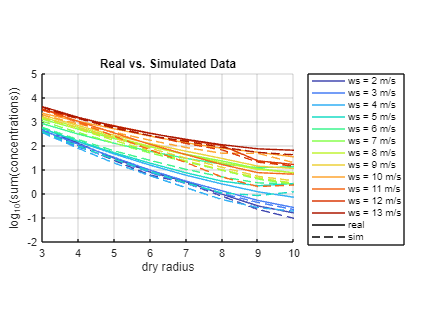

single_column_flux =   107.5041   44.7442   19.8435    9.8107    5.4039    3.5106    2.3742    1.8295
   98.8567   45.8369   17.6538    6.4336    2.7756    2.0199    0.9702    0.8612
    9.1344    2.4966    0.8057    0.3615    0.1733    0.1015    0.0784    0.0967
   70.6911   27.3648   11.3120    4.7640    2.1536    1.0970    0.6671    0.4485
  107.8375   35.6161    8.0186    1.8649    0.5349    0.1445    0.0589    0.0817
  107.8906   44.6795   19.6742    9.0339    4.7501    2.8418    1.8943    1.4284
  119.4858   65.5625   35.9821   20.4901   13.1550   10.3032   11.9812    6.7961
   29.0784    9.7033    3.4710    1.5718    0.7368    0.3488    0.2693    0.3321
  447.1829  176.1489   79.4679   37.3907   19.7459   12.0181    7.4842    5.8352
   37.7064   11.7733    4.5120    1.9829    0.8309    0.3435    0.1854    0.4006


% Plotting some comparisons between real and simulated data
sim_log10_means = zeros(wind_nbins,drad_nbins);
for i = 1:wind_nbins
    for j = 1:drad_nbins
        tmp_data = log10(nonzeros(sim_data{i,j})*correlation_time_vec(j));
        sim_log10_means(i,j) = mean(tmp_data);
    end
end

real_concs_log10_mean_by_ws = zeros(wind_nbins,drad_nbins);
for i = 1:wind_nbins
    for j = 1:drad_nbins
        real_concs_log10_mean_by_ws(i,j) = log10(mean(wsX_concs{i,j}*correlation_time_vec(j),"omitmissing"));
    end
end
real_concs_log10_mean_by_ws(real_concs_log10_mean_by_ws==-Inf) = NaN;

figure;
turbo = colormap("turbo");
cmap_scale = floor((size(turbo,1)-wind_nbins)/wind_nbins);
hold on
for i = 1:wind_nbins
    plot(3:1:10,sim_log10_means(i,:),'Color',turbo(i*cmap_scale,:),'LineStyle','--')
    plot(3:1:10,real_concs_log10_mean_by_ws(i,:),'Color',turbo(i*cmap_scale,:),'LineStyle','-')
    qw{i} = plot(nan,'Color', turbo(i*cmap_scale,:));
end
qw{14} = plot(nan,'Color', 'k', 'LineStyle', '-');
qw{15} = plot(nan,'Color', 'k', 'LineStyle', '--');

ylim([-2 5])
xlim([3 10])
xlabel("dry radius")
ylabel("log_{10}(sum(concentrations))")
title("Real vs. Simulated Data")
grid on
pbaspect([1.5 1 1])
legend([qw{:}], {"ws = 2 m/s","ws = 3 m/s","ws = 4 m/s","ws = 5 m/s","ws = 6 m/s","ws = 7 m/s","ws = 8 m/s","ws = 9 m/s","ws = 10 m/s","ws = 11 m/s","ws = 12 m/s","ws = 13 m/s","real","sim"}, 'location', 'bestoutside')

% % Sampling a day of wind from a gamma distribution based on real winds
% function wind_vec = random_wind_generator(num_hrs)
% min_ws = 0;   % minimum wind speed
% max_ws = 13;  % max wind speed
% max_step = 3; % max difference between time steps
% 
% % Initialize the wind vector
% wind_vec = zeros([num_hrs 1]);
% 
% % Select the first from a gamma dist. based on the wind histogram
% wind_vec(1) = gamrnd(9.9466, 0.7645);
% for i = 2:num_hrs
%     r = -max_step + (max_step+max_step)*rand(1); % random number between +/- max_step
%     wind_vec(i) = min(max(wind_vec(i-1) + r, min_ws), max_ws);
% end
% end

% Function for sampling aerosol concentrations based on simulated wind speeds
function [one_col_concs, sum_ts_one_col_concs, wind_vec] = sim_sum_concs(wsX_conc_cds,wsX_conc_xis,correlation_vector, real_wind_vector)
    num_hrs = 23;
    drad_nbins = 8;
    wind_gamma_dist = fitdist(real_wind_vector,"Gamma");
    wind_vec = gamrnd(wind_gamma_dist.a, wind_gamma_dist.b, num_hrs, 1);
    
    one_col_concs = zeros(num_hrs,drad_nbins);
    sim_wind = round(wind_vec);
    
    for j = 1:drad_nbins
        tmp_one_col_concs = zeros(num_hrs,1);
        for i = 1:num_hrs
            wind_rw = sim_wind(i);
            if wind_rw >= 13
                wind_rw = 12;
            elseif wind_rw <=1
                wind_rw = 1;
            end
    
            [tmp_cds, uni_idx] = unique(wsX_conc_cds{wind_rw,j});
            tmp_xis = abs(wsX_conc_xis{wind_rw,j});
            tmp_xis = tmp_xis(uni_idx);
    
            tmp_one_col_concs(i) = interp1(tmp_cds, tmp_xis, rand(1,1), 'linear', 'extrap');
        end
        one_col_concs(:,j) = tmp_one_col_concs;
    end

    sum_ts_one_col_concs = zeros(1,drad_nbins);
    for j = 1:drad_nbins
        sum_ts_one_col_concs(j) = sum(one_col_concs(1:correlation_vector(j),j),1);
    end
end

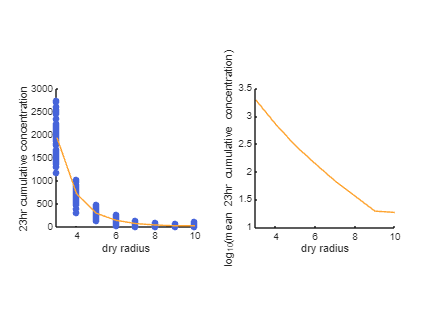

% Simulating multiple cumulative concentrations
nsims = 50;
sim_sum_ts_occ = zeros(nsims,drad_nbins);
for i = 1:nsims
    [~, sim_sum_ts_occ(i,:)] = sim_sum_concs(wsX_conc_cds,wsX_conc_xis,correlation_time_vec,ssa_df.total_wind);
end

figure;
tiledlayout(1,2);

nexttile;
scatter(3:10,sim_sum_ts_occ,[],turbo(30,:),"filled")
hold on
plot(3:10,mean(sim_sum_ts_occ,1),'Color',turbo(180,:))
hold off
xlabel("dry radius")
ylabel("23hr cumulative concentration")
pbaspect([1 1 1])

nexttile;
hold on
plot(3:10,log10(mean(sim_sum_ts_occ,1)),"Color",turbo(180,:))
hold off
xlabel("dry radius")
ylabel("log_{10}(mean 23hr cumulative concentration)")
pbaspect([1 1 1])

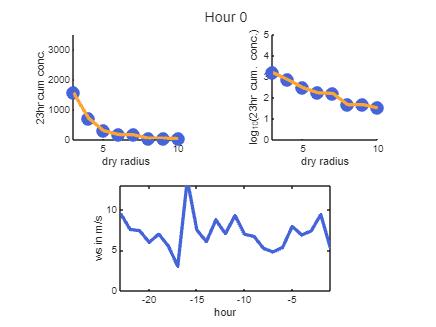

% Function for live sampling aerosol concentrations based on simulated wind speeds
[tst_one_col_concs, ~, tst_wind_vec] = sim_sum_concs(wsX_conc_cds,wsX_conc_xis,correlation_time_vec,ssa_df.total_wind);

initial_ts_one_col_concs = tst_one_col_concs;
wind_gamma_dist = fitdist(ssa_df.total_wind,"Gamma");
initial_wind_vec = gamrnd(wind_gamma_dist.a, wind_gamma_dist.b, 23, 1);
new_wind_vec = initial_wind_vec;
tcount = 0;

nframes = 1;
filename = "ssa_stat_model_test.gif";

% while true
for i = 1:nframes

    % Next wind vector
    new_wind_vec = new_wind_vec(2:end);
    next_ws = gamrnd(9.9466, 0.7645);
    new_wind_vec = cat(1,new_wind_vec,next_ws);

    % Next hourly concentration matrix
    new_ts_one_col_concs = initial_ts_one_col_concs(2:end,:);
    latest_ws = round(new_wind_vec(end));
    if latest_ws <= 1
        latest_ws = 1;
    elseif latest_ws >= 13
        latest_ws = 8;
    end
    
    tmp_one_col_concs = zeros(1,drad_nbins);
    for j = 1:drad_nbins
        [tmp_cds, uni_idx] = unique(wsX_conc_cds{latest_ws,j});
        tmp_xis = abs(wsX_conc_xis{latest_ws,j});
        tmp_xis = tmp_xis(uni_idx);
        tmp_one_col_concs(j) = interp1(tmp_cds, tmp_xis, rand(1,1), 'linear', 'extrap');
    end
    new_ts_one_col_concs = cat(1,new_ts_one_col_concs,tmp_one_col_concs);
    new_sum_23hr_one_col_concs = sum(new_ts_one_col_concs,1);

    figure(1);
    t = tiledlayout(2,2);
    title(t,"Hour " + string(tcount))

    nexttile(1);
    scatter(3:1:10,new_sum_23hr_one_col_concs,150,turbo(30,:),"filled")
    hold on
    plot(3:1:10,new_sum_23hr_one_col_concs,'Color',turbo(180,:),'LineWidth',3)
    hold off
    ylim([0 3500])
    xlim([3 10])
    xlabel("dry radius")
    ylabel("23hr cum conc.")
    pbaspect([1 1 1])
    drawnow;

    nexttile(2);
    scatter(3:1:10,log10(new_sum_23hr_one_col_concs),150,turbo(30,:),"filled")
    hold on
    plot(3:1:10,log10(new_sum_23hr_one_col_concs),'Color',turbo(180,:),'LineWidth',3)
    hold off
    ylim([0 5])
    xlabel("dry radius")
    ylabel("log_{10}(23hr cum. conc.)")
    pbaspect([1 1 1])
    drawnow;

    nexttile([1 2]);
    plot(-23:1:-1,new_wind_vec,'LineWidth',3,'Color',turbo(30,:))
    ylim([0 13])
    xlim([-23 -1])
    xlabel("hour")
    ylabel("ws in m/s")
    pbaspect([2 1 1])
    drawnow;

    pause(0.5)

    % % Capture the plot as an image
    % frame = getframe(gcf);
    % img = frame2im(frame); 
    % [A, map] = rgb2ind(img, 256); % Convert to indexed image with 256 colors
    % 
    % % Write to the GIF file
    % if i == 1
    %     % For the first frame, create the GIF file
    %     imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.5);
    % else
    %     % For subsequent frames, append to the GIF file
    %     imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.5);
    % end
    % 
    % tcount = tcount + 1;
end

wsX_conc_cds

wsX_conc_cds = 12×8 cell array
    {[    0 0.0189 0.0378 0.0567 0.0756 0.0945 0.1133 0.1321 0.1508 0.1695 0.1882 0.2067 0.2252 0.2436 0.2618 0.2800 0.2979 0.3158 0.3334 0.3509 0.3681 0.3852 0.4020 0.4186 0.4350 0.4512 0.4671 0.4828 0.4982 0.5135 0.5285 0.5433 0.5579 0.5723 0.5865 0.6006 0.6145 0.6282 0.6418 0.6553 0.6687 0.6819 0.6950 0.7080 0.7208 0.7335 0.7461 0.7585 0.7707 0.7828 0.7946 0.8062 0.8176 0.8287 0.8395 0.8500 0.8601 0.8700 0.8794 0.8885 0.8972 0.9055 0.9134 0.9208 0.9279 0.9345 0.9407 0.9465 0.9519 0.9569 0.9615 0.9657 0.9696 0.9731 0.9763 0.9792 0.9818 0.9841 0.9862 0.9881 0.9897 0.9912 0.9925 0.9936 0.9945 0.9954 0.9961 0.9967 0.9973 0.9977 0.9981 0.9984 0.9987 0.9989 0.9991 0.9993 0.9994 0.9995 0.9996 0.9997]}    {[        0 0.0240 0.0480 0.0720 0.0959 0.1197 0.1433 0.1668 0.1902 0.2133 0.2362 0.2589 0.2814 0.3036 0.3255 0.3471 0.3684 0.3893 0.4099 0.4302 0.4501 0.4696 0.4888 0.5075 0.5259 0.5438 0.5613 0.5785 0.5952 0.6115 0.6273 0.6428 0.6578 0.6724 0.6866 0.7004 0.

cdf_prob_vals_matrix = zeros(size(wsX_conc_cds,1),size(wsX_conc_cds,2)*100);
cdf_flux_vals_matrix = zeros(size(wsX_conc_cds,1),size(wsX_conc_cds,2)*100);

for i = 1:wind_nbins
    for j = 1:drad_nbins
        cdf_prob_vals_matrix(i,100*(j-1)+1:100*j) = wsX_conc_cds{i,j};
        cdf_flux_vals_matrix(i,100*(j-1)+1:100*j) = wsX_conc_xis{i,j};
    end
end
cdf_prob_vals_matrix

cdf_prob_vals_matrix =          0    0.0189    0.0378    0.0567    0.0756    0.0945    0.1133    0.1321    0.1508    0.1695    0.1882    0.2067    0.2252    0.2436    0.2618    0.2800    0.2979    0.3158    0.3334    0.3509    0.3681    0.3852    0.4020    0.4186    0.4350    0.4512    0.4671    0.4828    0.4982    0.5135    0.5285    0.5433    0.5579    0.5723    0.5865    0.6006    0.6145    0.6282    0.6418    0.6553    0.6687    0.6819    0.6950    0.7080    0.7208    0.7335    0.7461    0.7585    0.7707    0.7828
         0    0.0178    0.0357    0.0536    0.0716    0.0897    0.1079    0.1263    0.1447    0.1632    0.1818    0.2004    0.2190    0.2375    0.2560    0.2745    0.2928    0.3110    0.3291    0.3471    0.3649    0.3827    0.4005    0.4182    0.4359    0.4536    0.4712    0.4889    0.5067    0.5244    0.5422    0.5599    0.5775    0.5951    0.6125    0.6297    0.6467    0.6634    0.6798    0.6957    0.7112    0.7262    0.7406    0.7544    0.7675    0.7801    0.7919    0.

cdf_flux_vals_matrix

cdf_flux_vals_matrix =    -0.0000    1.0848    2.1696    3.2544    4.3391    5.4239    6.5087    7.5935    8.6783    9.7631   10.8479   11.9327   13.0174   14.1022   15.1870   16.2718   17.3566   18.4414   19.5262   20.6110   21.6957   22.7805   23.8653   24.9501   26.0349   27.1197   28.2045   29.2893   30.3740   31.4588   32.5436   33.6284   34.7132   35.7980   36.8828   37.9676   39.0523   40.1371   41.2219   42.3067   43.3915   44.4763   45.5611   46.6459   47.7306   48.8154   49.9002   50.9850   52.0698   53.1546
   -0.0000    0.8411    1.6821    2.5232    3.3642    4.2053    5.0463    5.8874    6.7284    7.5695    8.4105    9.2516   10.0927   10.9337   11.7748   12.6158   13.4569   14.2979   15.1390   15.9800   16.8211   17.6621   18.5032   19.3443   20.1853   21.0264   21.8674   22.7085   23.5495   24.3906   25.2316   26.0727   26.9137   27.7548   28.5959   29.4369   30.2780   31.1190   31.9601   32.8011   33.6422   34.4832   35.3243   36.1653   37.0064   37.8474   38.6885   39.